# Basic PID Loop Example

This script serves as an example to understand a basic PID loop in matlab, in conjunction with the trade study.

### Inputs

We will take a preliminary version of the IREC 27 vehicle and plot its roll rate straight from ork. This ork has its fin set to have a 0.1 degree cant to induce some roll for the controls system to fix.

% Import sim data and prepare state variables %
sim = readtable('Sim-Data.csv', VariableNamingRule='preserve');
sim_time = sim.("# Time (s)");
thrust = sim.("Thrust (N)");
p = sim.("Roll rate (r/s)");

[coasting, tBurnout] = burnEnded(thrust, sim_time);
p_burning = p(~coasting);

### Controller Settings

The following code block holds the PID values and some arbitrary control constants, for the sake of simplicity, we will simplify the canards force outputs to these constant values.

Kp = 1.8;   % Proportional gain
Ki = 0;   % Integral gain
Kd = 0;  % Derivative gain
p_target = 0; % target roll rate (rad/s)

b = 1;    % roll acceleration per unit command (rad/s^2 per unit)
u_max = 10; % actuator limit

### Disturbance

Inputting mild roll acceleration for the rocket to control with no control post burnout

a_dist = gradient(p, sim_time);

### SImulate the PID loop and controlled roll rate

n = numel(sim_time);
p_ctrl = p;
u = zeros(n, 1);    % control command history

k0 = find(coasting, 1); % first sample after burnout

integ = 0;
prevErr = p_target - p_ctrl(k0); % avoid derivative kick on first step of loop

for k = k0:n-1
    dt = sim_time(k+1) - sim_time(k);
    if dt <= 0                          % Skip duplicate timestamps
        p_ctrl(k+1) = p_ctrl(k);
        continue
    end

    err = p_target - p_ctrl(k);
    integ = integ + err*dt;
    deriv = (err - prevErr) / dt;

    uRaw = Kp*err + Ki*integ + Kd*deriv;    % ----Primary computation of the PID loop---- %
    u(k) = min(max(uRaw, -u_max), u_max);   % hold within actuator limits
    if u(k) ~= uRaw
        integ = integ - err*dt;
    end
    prevErr = err;

    % Eurler step: uncontrolled dynamics + control effect
    p_ctrl(k+1) = p_ctrl(k) + (a_dist(k) + b*u(k)) * dt;
end

## Plot

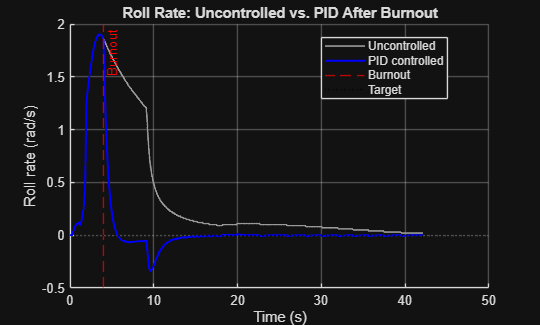

%% Plot
figure; hold on; grid on
plot(sim_time, p,      'Color', [0.6 0.6 0.6], 'LineWidth', 1.2, 'DisplayName', 'Uncontrolled')
plot(sim_time, p_ctrl, 'b', 'LineWidth', 1.5, 'DisplayName', 'PID controlled')
xline(tBurnout, '--r', 'Burnout', 'DisplayName', 'Burnout')
yline(p_target, ':k', 'DisplayName', 'Target')
xlabel('Time (s)')
ylabel('Roll rate (rad/s)')
title('Roll Rate: Uncontrolled vs. PID After Burnout')
legend('Location', 'best')
hold off